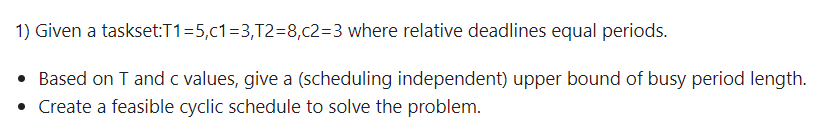

T = [5;8];
C = [3;3];
D = T;

L=lcm(T(1),T(2))

L = 40


U = [0,0];
for i = 1:2
  U(i) = C(i)/T(i);
end
 %up = up + C(i)/T(i)+C(i);
  %down = down + C(i)/T(i)-C(i);
sum(U)

ans = 0.9750

sum(U) < 1

ans = logical
   1


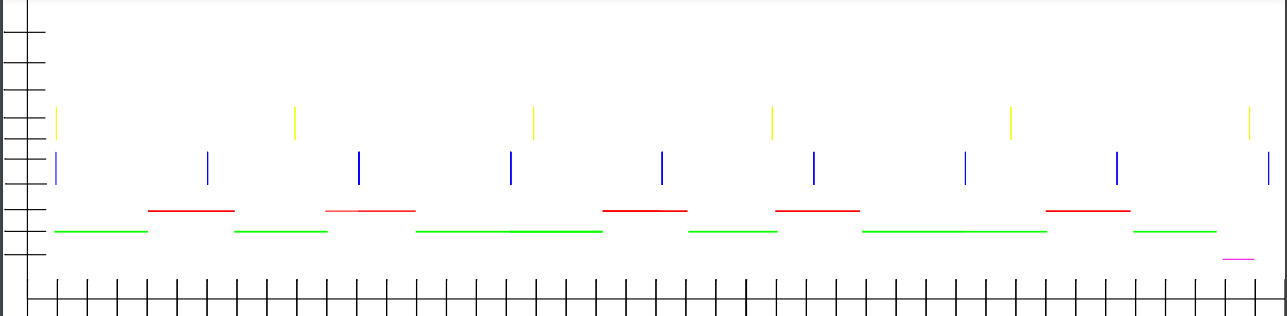

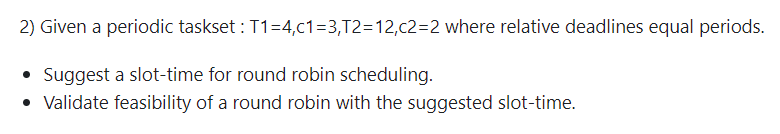

slot_time = 1

slot_time = 1

T = [4;12]/slot_time;
C = [3;2]/slot_time;
D = T;

% T1 not feasible
c1n=T(1)/T(1)*C(1)

c1n = 3

c2n=T(1)/T(2)*C(2)

c2n = 0.6667


% T2 is feasible
c1n=ceil(T(2)/T(1)*C(1))

c1n = 9

c2n=ceil(T(2)/T(2)*C(2))

c2n = 2

F = c1n+c2n

F = 11

F <= T(2)

ans = logical
   1


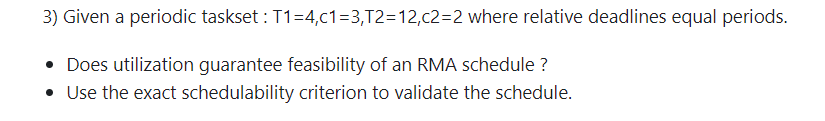

% Define task parameters
T = [4;12];
C = [3;2];
D = T;

% Calculate utilization
U = C./T;

% Print the sum of utilization
disp(sum(U))

    0.9167



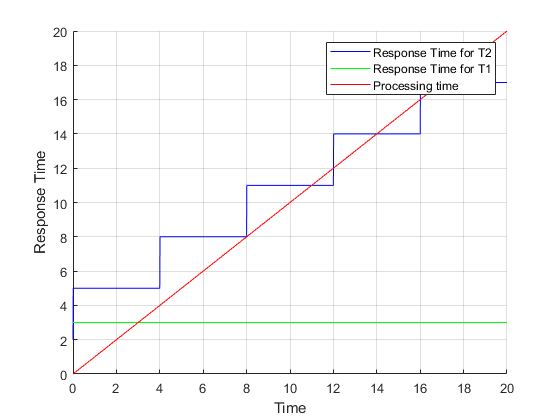


% Define time scale for the plot
x=0:0.01:20;

% Calculate response time for task T2
R1 = C(1)*ceil(x/T(1));
R2 = C(2) + R1;

% Create the plot
figure
hold on
plot(x, R2, 'b') % Response time for T2
plot([0 max(x)], [C(1) C(1)], 'g') % Response time for T1
plot(x, x, 'r')  % Line y = x

xlabel('Time')
ylabel('Response Time')
legend('Response Time for T2', 'Response Time for T1','Processing time')
grid on
hold off

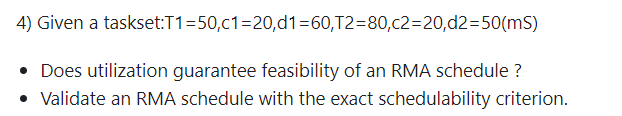

T = [50;80];
C = [20;20];
D = [60;50];

U = [0,0];
for i = 1:2
  U(i) = C(i)/D(i);
end
sum(U)

ans = 0.7333

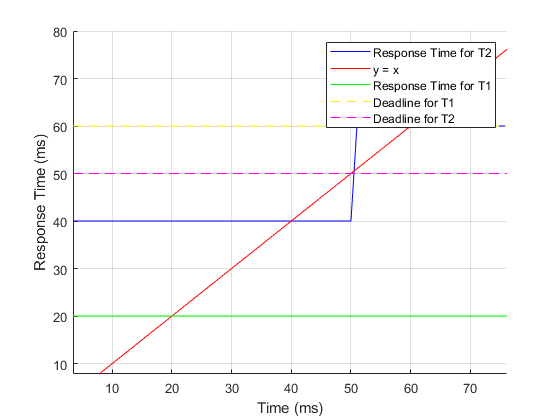


% Define time scale for the plot
x = 0:1:max(T);

% Calculate response times for each task
R1 = C(1) * ceil(x / T(1));
R2 = C(2) + R1;

% Create the plot
figure
hold on
plot(x, R2, 'b') % Response time for T2
plot(x, x, 'r')  % Line y = x
plot([0 max(x)], [C(1) C(1)], 'g') % Response time for T1
plot([0 max(x)], [D(1) D(1)], 'y--') % Deadline for T1
plot([0 max(x)], [D(2) D(2)], 'm--') % Deadline for T2
xlabel('Time (ms)')
ylabel('Response Time (ms)')
legend('Response Time for T2', 'Processing time', 'Response Time for T1', 'Deadline for T1', 'Deadline for T2')
grid on
hold off

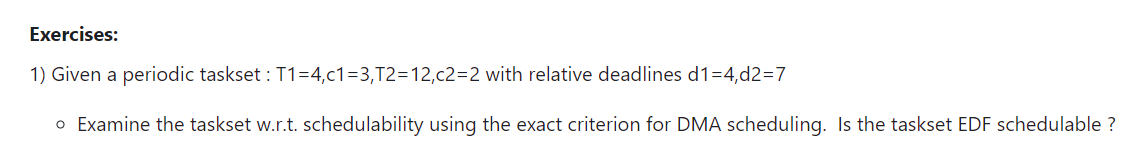

% Define task parameters
T = [4;12]; % periods
C = [3;2];  % execution times
D = [4;7];  % relative deadlines

% Number of tasks
n = length(C);

% Calculate utilization
U = sum(C./T);
disp(['Total Utilization: ', num2str(U)])

Total Utilization: 0.91667



% Initialize response times with execution times
R = C;

% Check for deadline miss (initally no deadline miss)
miss = 0;

% Iteratively calculate response times
for i = 1:n
    while true
        W = C(i);
        for j = 1:i-1
            W = W + ceil(R(i) / T(j)) * C(j);
        end
        if W == R(i)
            break;
        elseif W > D(i)
            miss = 1;
            break;
        else
            R(i) = W;
        end
    end
    if miss == 1
        break;
    end
end

% Print and plot results
if miss == 1
    fprintf('Task %d cannot meet its deadline under DMA.\n', i);
else
    fprintf('All tasks can meet their deadlines under DMA.\n');
end

Task 2 cannot meet its deadline under DMA.


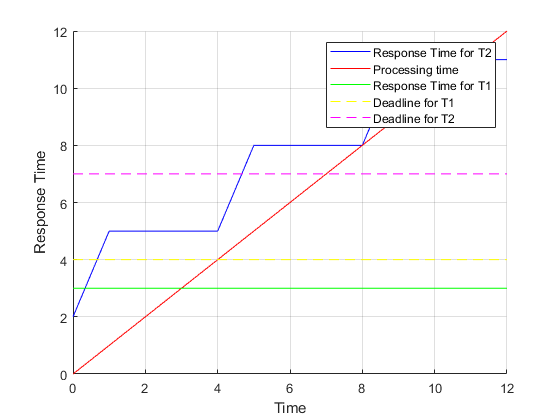


% Define time scale for the plot
x = 0:1:max(T);

% Calculate response times for each task
R1 = C(1) * ceil(x / T(1));
R2 = C(2) + R1;

% Create the plot
figure
hold on
plot(x, R2, 'b') % Response time for T2
plot(x, x, 'r')  % Line y = x
plot([0 max(x)], [C(1) C(1)], 'g') % Response time for T1
plot([0 max(x)], [D(1) D(1)], 'y--') % Deadline for T1
plot([0 max(x)], [D(2) D(2)], 'm--') % Deadline for T2
xlabel('Time')
ylabel('Response Time')
legend('Response Time for T2', 'Processing time', 'Response Time for T1', 'Deadline for T1', 'Deadline for T2')
grid on
hold off

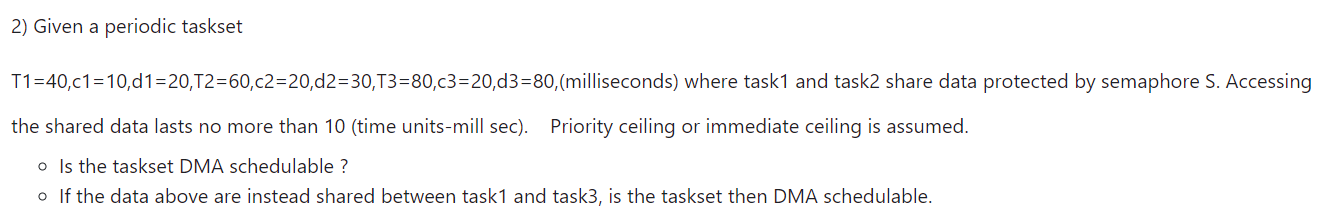

% Define task parameters
T = [40;60;80]; % periods
C = [10;20;20]; % execution times
D = [20;30;80]; % relative deadlines

% Add blocking times due to semaphore usage
% For scenario 1: T1 and T2 share data
C1 = C + [0;10;0];
% For scenario 2: T1 and T3 share data
C2 = C + [0;0;10];

% Number of tasks
n = length(C);

% Initialize response times with execution times
R1 = C1;
R2 = C2;

% Iteratively calculate response times for both scenarios
for i = 1:n
    while true
        W1 = C1(i);
        W2 = C2(i);
        for j = 1:i-1
            W1 = W1 + ceil(R1(i) / T(j)) * C1(j);
            W2 = W2 + ceil(R2(i) / T(j)) * C2(j);
        end
        if W1 > D(i) || W2 > D(i)
            fprintf('Task %d cannot meet its deadline under DMA.\n', i);
            break;
        elseif W1 == R1(i) && W2 == R2(i)
            break;
        else
            R1(i) = W1;
            R2(i) = W2;
        end
    end
end

Task 2 cannot meet its deadline under DMA.
Task 3 cannot meet its deadline under DMA.


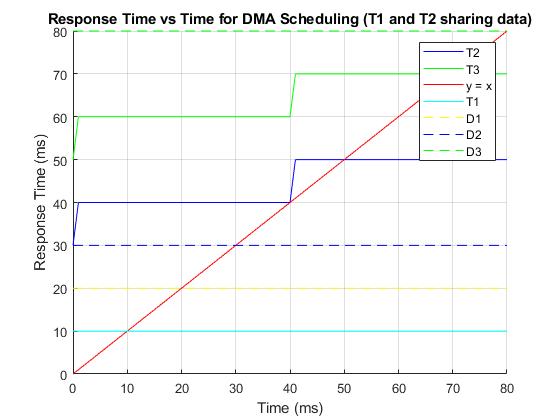


% Define time scale for the plot
x = 0:1:max(T);

% Calculate response times for each task
R1_1 = C1(1) * ceil(x / T(1));
R1_2 = C1(2) + R1_1;
R1_3 = C1(3) + R1_2;

R2_1 = C2(1) * ceil(x / T(1));
R2_2 = C2(2) + R2_1;
R2_3 = C2(3) + R2_2;

% Create the plot for scenario 1
figure
hold on
plot(x, R1_2, 'b') % Response time for T2
plot(x, R1_3, 'g') % Response time for T3
plot(x, x, 'r')  % Line y = x
plot([0 max(x)], [C1(1) C1(1)], 'c') % Response time for T1
plot([0 max(x)], [D(1) D(1)], 'y--') % Deadline for T1
plot([0 max(x)], [D(2) D(2)], 'b--') % Deadline for T2
plot([0 max(x)], [D(3) D(3)], 'g--') % Deadline for T3
xlabel('Time (ms)')
ylabel('Response Time (ms)')
title('Response Time vs Time for DMA Scheduling (T1 and T2 sharing data)')
legend('T2', 'T3', 'Processing time', 'T1', 'D1', 'D2', 'D3')
grid on
hold off

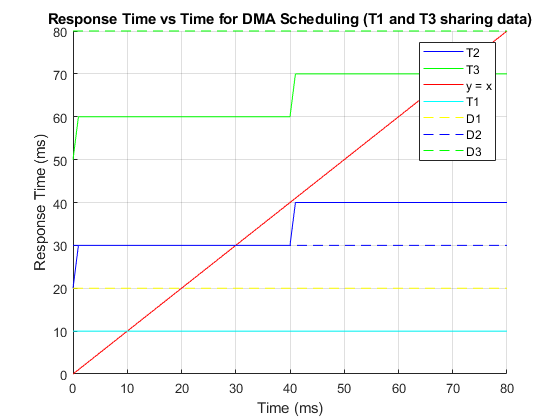


% Create the plot for scenario 2
figure
hold on
plot(x, R2_2, 'b') % Response time for T2
plot(x, R2_3, 'g') % Response time for T3
plot(x, x, 'r')  % Line y = x
plot([0 max(x)], [C2(1) C2(1)], 'c') % Response time for T1
plot([0 max(x)], [D(1) D(1)], 'y--') % Deadline for T1
plot([0 max(x)], [D(2) D(2)], 'b--') % Deadline for T2
plot([0 max(x)], [D(3) D(3)], 'g--') % Deadline for T3
xlabel('Time (ms)')
ylabel('Response Time (ms)')
title('Response Time vs Time for DMA Scheduling (T1 and T3 sharing data)')
legend('T2', 'T3', 'Processing time', 'T1', 'D1', 'D2', 'D3')
grid on
hold off

## Mini Project

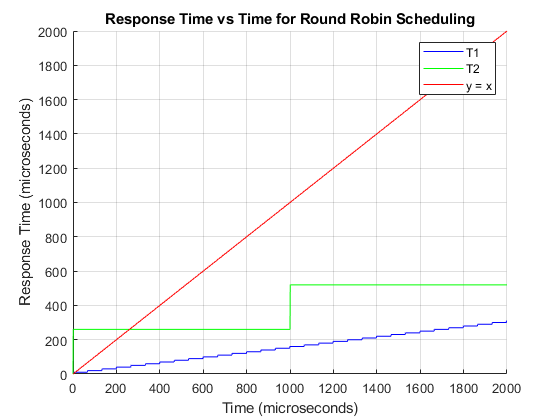


% Define task parameters
T = [66.6; 1000]; % periods in microseconds
C = [10; 260];    % execution times in microseconds

% Number of tasks
n = length(C);

% Define time scale for the plot
x = 0:1:max(T)*2;

% Calculate response times for each task
R1 = C(1) * ceil(x / T(1));
R2 = C(2) * ceil(x / T(2));

% Create the plot for round robin scheduling
figure
hold on
plot(x, R1, 'b') % Response time for T1
plot(x, R2, 'g') % Response time for T2
plot(x, x, 'r')  % Line y = x
xlabel('Time (microseconds)')
ylabel('Response Time (microseconds)')
title('Response Time vs Time for Round Robin Scheduling')
legend('T1', 'T2', 'y = x')
grid on
hold off

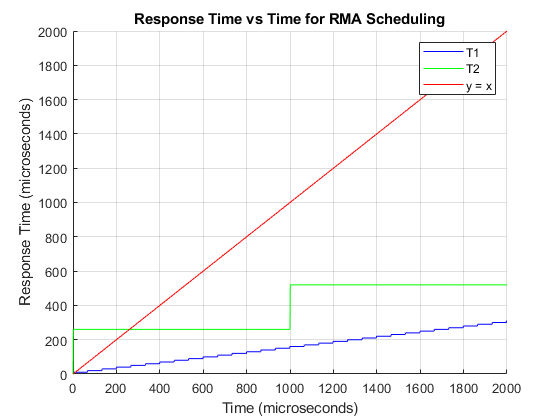


% Create the plot for RMA scheduling
figure
hold on
plot(x, R1, 'b') % Response time for T1
plot(x, R2, 'g') % Response time for T2
plot(x, x, 'r')  % Line y = x
xlabel('Time (microseconds)')
ylabel('Response Time (microseconds)')
title('Response Time vs Time for RMA Scheduling')
legend('T1', 'T2', 'y = x')
grid on
hold off